## Group 9 Initial Weight estimation by Larry, Tony, Matthew

To use this code: Use known values of your aircraft, and apply into a new case under AircraftData.m

Last updated 21:44 06/02/2024

clear
aircraftname = "B"; %Select your case
AircraftData 
%DATA FROM AIRCRAFTDATA
    cruiseMach = Aircraft.CruiseMach;
    engines = Aircraft.Engines;  
    
 
%Segments for A 
    warmupSegment = 0.995; %Assumed
    takeOffSegment = 0.99; %Assumed
    climbSegment = 0.98; %Assumed
        cruiseSegment = getCruiseSegment("A"); %Cruise function
    descentSegment = 0.995; %Assumed
    landingSegment = 0.995; %Assumed
    taxiSegment = 0.9990;%Assumed
        loiterSegment = 0.9848; %getloiterSegment();  
    altClimb = 0.990;%Assumed
        altCruise = getDiversionSegment("A"); %Diversion function 
    altLanding = 0.995; %Assumed
    reserveFuel = 1/1.05; %Calculated
    
%Formatting into an array
    segment = [warmupSegment;takeOffSegment;climbSegment;cruiseSegment;descentSegment;...
    landingSegment;loiterSegment;taxiSegment;altClimb;altCruise;altLanding;reserveFuel];
    missionSegment = zeros(length(segment));


%%Find the mission Segment - Indexes of segment * lastMissionSegment (W/ Exception) 
    for i = 1:length(segment)
        if i == 1 %Exception - First index of segment, missionSegment = warmupsegment
            missionSegment(1) = warmupSegment; 
            lastMissionSegment = missionSegment(1);
        else
          missionSegment(i) = segment(i)*lastMissionSegment;
          lastMissionSegment = missionSegment(i);

        end
    end

%Table plotting
    segmentType = ["WARM";"TKOF";"CLMB";"CRUS";"DSCT";"LNDG";"HOLD";"TAXI";"ALCL";"ALCR";"ALLD";"RSRV"];
    Table = table(segment(:,1),missionSegment(:,1),segmentType(:,1), ...
        'VariableNames',["Segment Fraction","Mission Segment","Segment Type"])

Table = 12×3 table
    Segment Fraction    Mission Segment    Segment Type
    ________________    _______________    ____________

          0.995               0.995           "WARM"   
           0.99             0.98505           "TKOF"   
           0.98             0.96535           "CLMB"   
        0.78965             0.76229           "CRUS"   
          0.995             0.75848           "DSCT"   
          0.995             0.75469           "LNDG"   
         0.9848             0.74322           "HOLD"   
          0.999             0.74247           "TAXI"   
           0.99             0.73505           "ALCL"   
        0.99216             0.72929           "ALCR"   
          0.995             0.72564           "ALLD"   
        0.95238             0.69108           "RSRV"   


%Weight Table
    passenger = Aircraft.Pax;
    bags = Aircraft.Bags;
    cargo = Aircraft.Cargo;
    maxPayload = Aircraft.MaxPyld;
    range = Aircraft.Range;
    passengerWeight = Aircraft.PaxWeight;
    bagWeight = Aircraft.BagWeight;
    MTOW = round(getWeightEstimation(missionSegment(12),"A"),-3);
    WeW0 = 0.97*MTOW^(-0.06);
    EmptyWeight = round(MTOW*WeW0,-3); 
    DesignPayload = Aircraft.Pax*Aircraft.PaxWeight + Aircraft.Bags*Aircraft.BagWeight; 
    MaxPayload = Aircraft.MaxPyld; 
    DesignFuel = round(MTOW * (1-missionSegment(12)),-3);
    WeightTbl = table([MTOW;EmptyWeight;DesignPayload;MaxPayload;DesignFuel],'RowNames',["Max Takeoff Weight", "Empty Weight", "Design Payload", "Maximum Payload", "Aircraft Design Fuel"],'VariableNames',"Weights (kg)")

WeightTbl = 5×1 table
                            Weights (kg)
                            ____________

    Max Takeoff Weight         81000    
    Empty Weight               40000    
    Design Payload             32500    
    Maximum Payload            75000    
    Aircraft Design Fuel       25000    


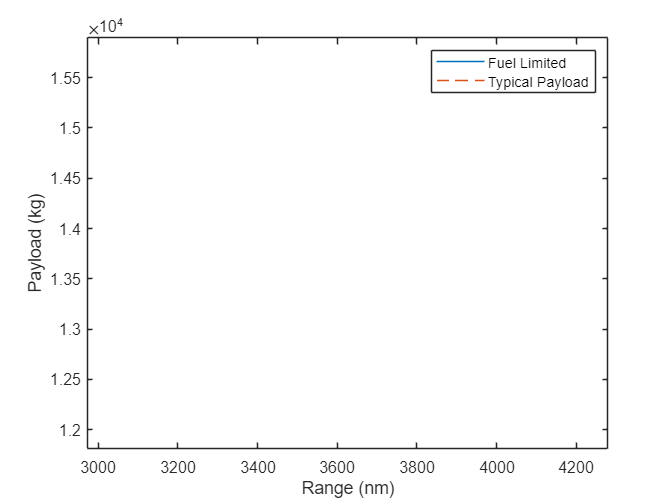

payloadRange = getpyldRangeEstimator('A',MTOW);
ferryRange = getferryRangeEstimator('A',MTOW,missionSegment(12));
plot([0, payloadRange, Aircraft.Range, ferryRange],[Aircraft.MaxPyld,Aircraft.MaxPyld,DesignPayload,0])
hold on
plot ([0, payloadRange, Aircraft.Range],[DesignPayload,DesignPayload,DesignPayload],'--')
hold off
legend(["Fuel Limited", "Typical Payload"])

xlabel("Range (nm)")
ylabel("Payload (kg)")
ax = gca;
chart = ax.Children(1);
chart.DataTipTemplate.DataTipRows(1).Label="Range";
chart.DataTipTemplate.DataTipRows(2).Label="Payload";
datatip(chart,Aircraft.Range,DesignPayload);

xlim([2972 4280])
ylim([11810 15898])


WingLoading = linspace(1000,15000,281);
ThrustWeight = linspace(0,1,281);
takeOffConstraint = zeros(281,1);
climbConstraint = zeros(281,1);
cruiseConstraint = zeros(281,1); 
landingConstraint = zeros(281,1);
cellingConstraint = zeros(281,1);
mu = zeros(281,1);

alpha = atan(Aircraft.Constraints(2).ClimbGradient/100); 

[~,~,rho,~] = get_AtmosProperties(0);
[~,~,rhoCruise,a] = get_AtmosProperties(Aircraft.CruiseAlt*0.3048);
[~,~,rhoCelling,aCelling] = get_AtmosProperties(41000*0.3048);
cruiseSpeed = Aircraft.CruiseMach*a;
cellSpeed = Aircraft.CruiseMach*aCelling;
q = 1/2*rhoCruise*cruiseSpeed^2;
q2 = 1/2*rhoCelling*cellSpeed^2;
k = 1/(pi*Aircraft.e*Aircraft.AR); 
LD_climb = 1/sqrt(4*Aircraft.CD0*k);
 y = 1; 
for i = 1:281
    takeOffConstraint(i) = (1.2^2/(Aircraft.CL_TO*rho*9.81*Aircraft.Constraints(1) ...
        .Distance*Aircraft.groundRollFraciton))*WingLoading(i); %somewhat works tiny difference (0.04~)
    climbConstraint(i) = (alpha + 1/LD_climb)*2*1.3; %works 0.001 difference
    cruiseConstraint(i) = (0.9653/0.29)*(((Aircraft.CD0*q)/(0.9653*WingLoading(i))...
        +((0.9653*k)/q)*WingLoading(i)));%Works
    cellingConstraint(i) = (0.7623/0.29)*(((Aircraft.CD0*q2)/(0.7623*WingLoading(i))...
        +((0.7623*k)/q2)*WingLoading(i)));%Works
   %mu(i) = ((1.2*sqrt((2/(rho*Aircraft.CL_Ld))*WingLoading(i)))^2)/(2*Aircraft.Constraints(3).Distance*9.81); % [-] An array of friction with respect to wingloading
        %landingConstraint(i) = (0.6*(Aircraft.Constraints(3).Distance-300)*WingLoading(i))/(Aircraft.Constraints(3).Distance*Aircraft.Constraints(3).Beta);%0.8764;%0.7755;
         %landingConstraint(i) = ((1/missionSegment(5))*(0.6*(Aircraft.Constraints(3).Distance-300)*9.81*mu(i)*rho*Aircraft.CL_Ld))/(1.2^2); % [-] Landing constraint Using summation of 2 dummy values @ their interaction to find the right xline value 
    mu(i) = ((1.2*sqrt((2/(rho*Aircraft.CL_Ld))*WingLoading(i)))^2)/(2*2000*9.81);
    landingConstraint(i) = ((1/0.7547)*(0.6*(2000-300)*9.81*mu(i)*rho*Aircraft.CL_Ld))/(1.2^2);
    
    
    if 6975 - landingConstraint(i) <= 1 && 6975 && y == 1
        disp(ThrustWeight(i))
        y = 0;
    end
    if ThrustWeight(i) == 0
        value1 = landingConstraint(i);
    elseif ThrustWeight(i) == 0.5
        value2 = landingConstraint(i);
        value3 = value1 + value2;
    end
    dummy1(i) = 0; 
    dummy2(i) = 0.5;
end

    0.6679



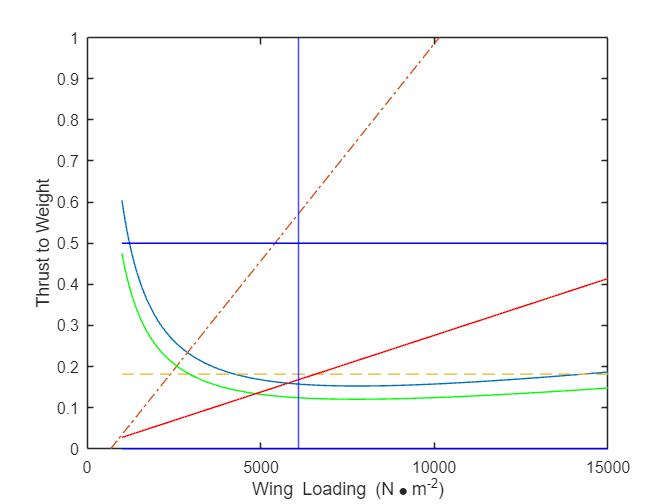

figure
hold on 
xline(value3,"b");
plot(WingLoading,cruiseConstraint,"-")
plot(landingConstraint,ThrustWeight,"-.")
plot(WingLoading,climbConstraint,"--")
plot(WingLoading,cellingConstraint, "g")
plot(WingLoading,dummy1,"b")
 plot(WingLoading,dummy2,"b")
plot(WingLoading,takeOffConstraint,"r")
xlabel("Wing Loading (N\bulletm^{-2})");
ylabel("Thrust to Weight");
box on
hold off

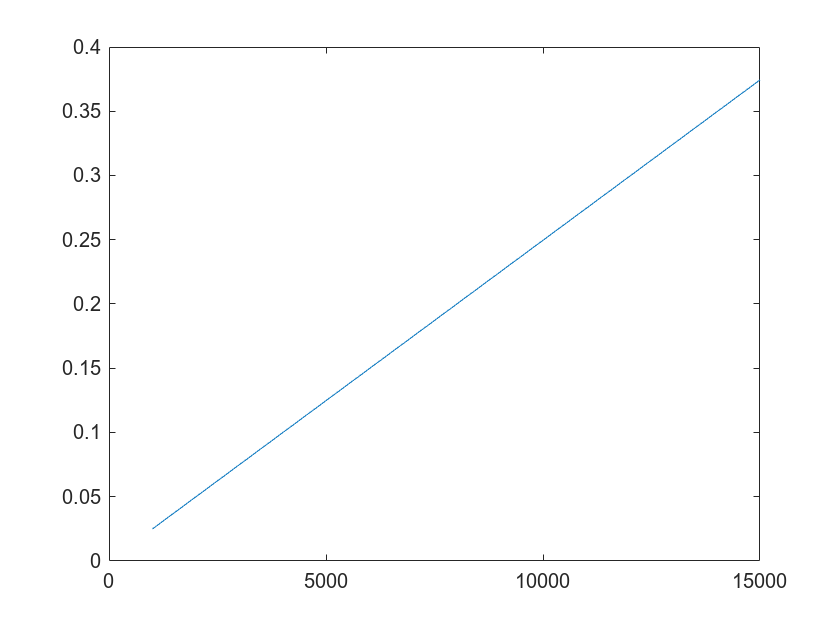

plot(WingLoading,mu)









%MissionTbl=table(MissionTable.WeightFractions(:,1), MissionTable.WeightFractions(:,2), MissionTable.WeightFractions(:,3), 'VariableNames', ["Segment Fraction", "Mission Fraction", "Segment Type"]);
